Peter Corke Simulation of Left Leg Exoskeleton Sit to Stand and Stand to Sit

startup_rvc

Robotics, Vision & Control: (c) Peter Corke 1992-2019 http://www.petercorke.com
Neither Robotics Toolbox or MachineVision Toolbox found in C:\Users\allen\AppData\Roaming\MathWorks\MATLAB Add-Ons\Toolboxes\Robotics Toolbox for MATLAB\lib
     ** this is at least 2 years old, you may have issues
** Toolbox function rotx is shadowed by C:\Program Files\MATLAB\R2023b\toolbox\phased\phased\rotx.m
** Toolbox function roty is shadowed by C:\Program Files\MATLAB\R2023b\toolbox\phased\phased\roty.m
** Toolbox function rotz is shadowed by C:\Program Files\MATLAB\R2023b\toolbox\phased\phased\rotz.m
** Toolbox function angdiff is shadowed by C:\Program Files\MATLAB\R2023b\toolbox\shared\robotics\robotutils\angdiff.m
Some Toolbox files are "shadowed" and will cause problems with the use of this toolbox
Use path tool to move this Toolbox to the top of the path


disp("Left Leg")

Left Leg


syms a1 a2 a3 a4 a5

a1 = 0.100  % 100mm = 0.100 m

a1 = 0.1000

a2 = 0.367  % 367mm = 0.367 m

a2 = 0.3670

a3 = 0.3436 % 343.6mm = 0.3436m

a3 = 0.3436

a4 = 0.06553 % 65.53mm = 0.06553 m

a4 = 0.0655

a5 = 0.0865 % 86.5mm = 0.0865m

a5 = 0.0865


H_L0L1 = Revolute('offset', pi/2, 'alpha', 3*pi/2, 'd', a1, 'qlim', [0 0])

 
H_L0L1 = 
Revolute(std): theta=q, d=0.1, a=0, alpha=4.71239, offset=1.5708


H_L1L2 = Revolute('offset', pi/2, 'a', a2, 'qlim', [-30*pi/180 140*pi/180])

 
H_L1L2 = 
Revolute(std): theta=q, d=0, a=0.367, alpha=0, offset=1.5708


H_L2L3 = Revolute('a', a3, 'qlim', [-140*pi/180 0])

 
H_L2L3 = 
Revolute(std): theta=q, d=0, a=0.3436, alpha=0, offset=0


H_L3L4 = Revolute('a', a4, 'd', -a5, 'qlim', [-50*pi/180 -30*pi/180])

 
H_L3L4 = 
Revolute(std): theta=q, d=-0.0865, a=0.06553, alpha=0, offset=0



RightLEG = SerialLink([H_L0L1 H_L1L2 H_L2L3 H_L3L4], 'name', "Left Leg Exoskeleton")

 
RightLEG = 
 
Left Leg Exoskeleton:: 4 axis, RRRR, stdDH, slowRNE              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        0.1|          0|    4.71239|     1.5708|
|  2|         q2|          0|      0.367|          0|     1.5708|
|  3|         q3|          0|     0.3436|          0|          0|
|  4|         q4|    -0.0865|    0.06553|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


RightLEG.plot([0,0,0,0])

standsit = jtraj(deg2rad([0,-15,0,5]), deg2rad([0, 70, -90, 20]), 20)

standsit =          0   -0.2618         0    0.0873
         0   -0.2598   -0.0021    0.0876
         0   -0.2471   -0.0156    0.0899
         0   -0.2164   -0.0481    0.0953
         0   -0.1634   -0.1042    0.1046
         0   -0.0869   -0.1852    0.1181
         0    0.0120   -0.2899    0.1356
         0    0.1305   -0.4154    0.1565
         0    0.2640   -0.5567    0.1801
         0    0.4069   -0.7080    0.2053


sitstand = jtraj(deg2rad([0, 70, -90, 20]), deg2rad([0,-15,0,5]), 20)

sitstand =          0    1.2217   -1.5708    0.3491
         0    1.2197   -1.5687    0.3487
         0    1.2070   -1.5552    0.3465
         0    1.1763   -1.5227    0.3410
         0    1.1233   -1.4666    0.3317
         0    1.0469   -1.3856    0.3182
         0    0.9479   -1.2808    0.3007
         0    0.8294   -1.1554    0.2798
         0    0.6959   -1.0141    0.2563
         0    0.5530   -0.8628    0.2311


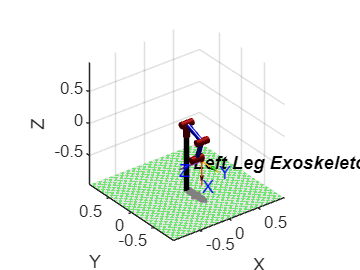

RightLEG.plot(standsit)